# Robot PKM

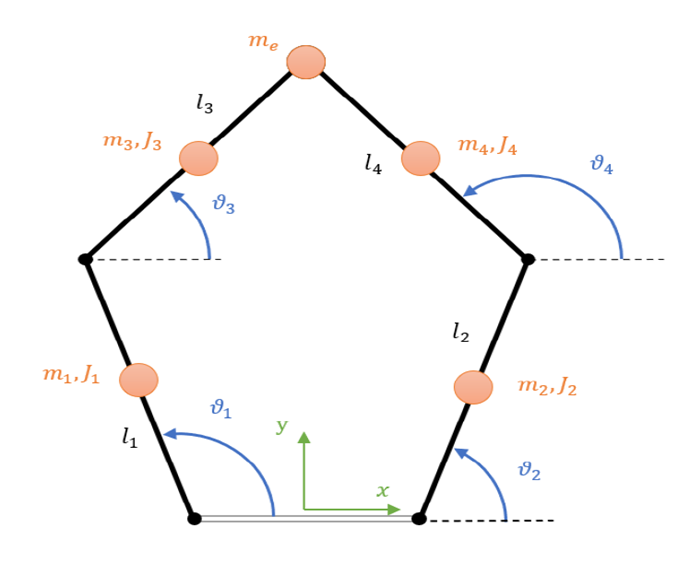

##   Definizione dati e informazioni utili manipolatore 

[PKM] = Define_Robot();

% Definizione parametri di test
theta1 = deg2rad(90); % Condizione iniziale posizione Theta1
theta2 = deg2rad(90); %  Condizione iniziale posizione Theta2
thetaV = deg2rad(720); % Angolo proprio della vite

theta1_p = 0; %  Condizione iniziale velocità theta1
theta2_p = 0; %  Condizione iniziale velocità tehta2
thetaV_p = 0; % Velocita thetav di prova

theta1_pp = 0; %  Condizione iniziale accelerazione theta1
theta2_pp = 0; %  Condizione iniziale accelarazione theta2
thetaV_pp = 0; % Accelerazione thetav di prova

## Legge di moto

Ldm_theta = struct with fields:
    vldm: {4×1 cell}
    name: 'ldm composta PKM'
    time: [1×1 struct]
    disp: [1×1 struct]
    moto: [1×1 struct]


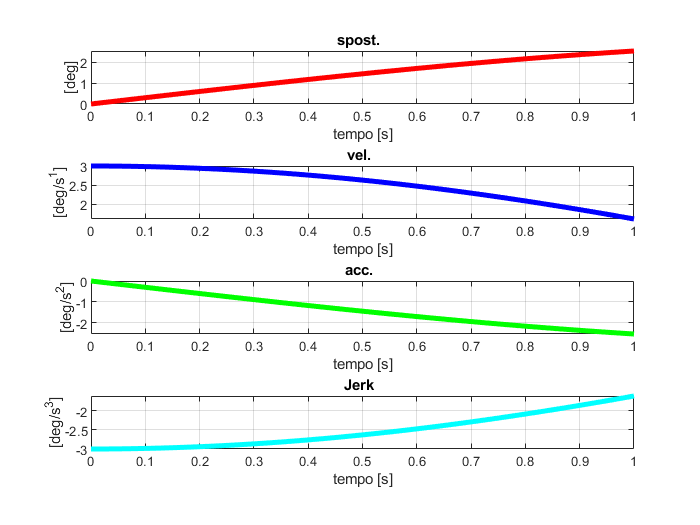

Ldm_theta1 = struct with fields:
    vldm: {4×1 cell}
    name: 'ldm composta PKM'
    time: [1×1 struct]
    disp: [1×1 struct]
    moto: [1×1 struct]


[Ldm_theta1] = Define_ldm(3, 'Sin') % Definisce una legge di moto data l'alzata in gradi per theta1

Ldm_theta = struct with fields:
    vldm: {4×1 cell}
    name: 'ldm composta PKM'
    time: [1×1 struct]
    disp: [1×1 struct]
    moto: [1×1 struct]


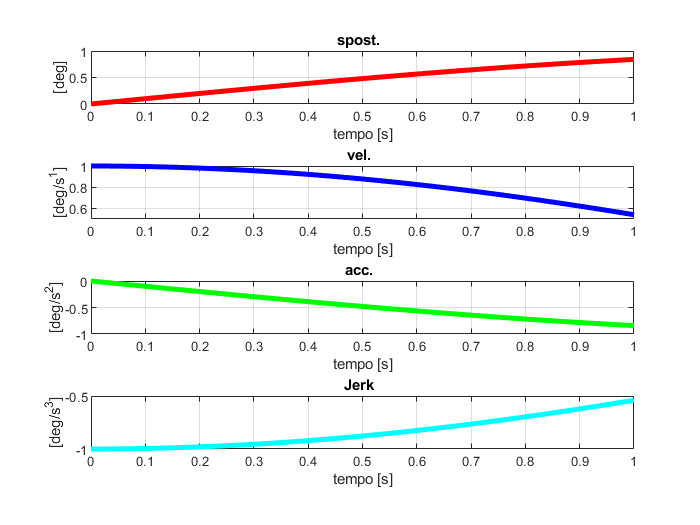

Ldm_theta2 = struct with fields:
    vldm: {4×1 cell}
    name: 'ldm composta PKM'
    time: [1×1 struct]
    disp: [1×1 struct]
    moto: [1×1 struct]


[Ldm_theta2] = Define_ldm(1, 'Sin') % Definisce una legge di moto data l'alzata in gradi per theta2

Ldm_theta = struct with fields:
    vldm: {4×1 cell}
    name: 'ldm composta PKM'
    time: [1×1 struct]
    disp: [1×1 struct]
    moto: [1×1 struct]


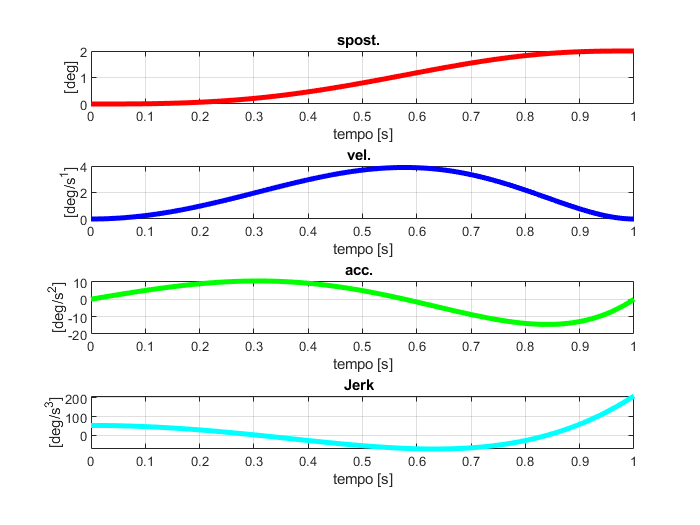

Ldm_thetav = struct with fields:
    vldm: {4×1 cell}
    name: 'ldm composta PKM'
    time: [1×1 struct]
    disp: [1×1 struct]
    moto: [1×1 struct]


[Ldm_thetav] = Define_ldm(2, 'pol357') % Definisce una legge di moto per la vite


theta1ldm = theta1 + Ldm_theta1.moto.data{1,1}.v;
theta2ldm = theta2 + Ldm_theta2.moto.data{1,1}.v;
thetavldm = thetaV + Ldm_thetav.moto.data{1,1}.v;

Theta = [theta1ldm; theta2ldm; thetavldm]

Theta =     1.5708    1.5738    1.5768    1.5798    1.5828    1.5858    1.5888    1.5918    1.5948    1.5978    1.6008    1.6038    1.6068    1.6098    1.6128    1.6158    1.6188    1.6218    1.6248    1.6278    1.6309    1.6339    1.6369    1.6399    1.6429    1.6459    1.6489    1.6519    1.6549    1.6579    1.6609    1.6639    1.6669    1.6699    1.6729    1.6759    1.6789    1.6819    1.6849    1.6879    1.6909    1.6939    1.6969    1.6999    1.7029    1.7059    1.7089    1.7119    1.7149    1.7179
    1.5708    1.5718    1.5728    1.5738    1.5748    1.5758    1.5768    1.5778    1.5788    1.5798    1.5808    1.5818    1.5828    1.5838    1.5848    1.5858    1.5868    1.5878    1.5888    1.5898    1.5908    1.5918    1.5928    1.5938    1.5948    1.5958    1.5968    1.5978    1.5988    1.5998    1.6008    1.6018    1.6028    1.6038    1.6048    1.6058    1.6068    1.6078    1.6088    1.6098    1.6108    1.6118    1.6128    1.6138    1.6148    1.6158    1.6168    1.6178    1.6188 

## Cinematica diretta

**Analisi di posizione**

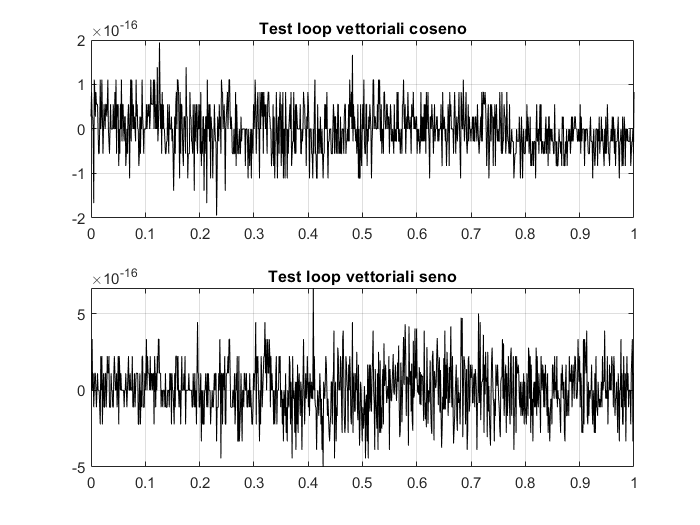

P =     0.0000   -0.0005   -0.0010   -0.0015   -0.0020   -0.0025   -0.0030   -0.0036   -0.0041   -0.0046   -0.0051   -0.0057   -0.0062   -0.0067   -0.0072   -0.0078   -0.0083   -0.0089   -0.0094   -0.0099   -0.0105   -0.0110   -0.0116   -0.0121   -0.0127   -0.0133   -0.0138   -0.0144   -0.0149   -0.0155   -0.0161   -0.0166   -0.0172   -0.0178   -0.0183   -0.0189   -0.0195   -0.0201   -0.0206   -0.0212   -0.0218   -0.0224   -0.0230   -0.0236   -0.0242   -0.0247   -0.0253   -0.0259   -0.0265   -0.0271
    0.4832    0.4831    0.4830    0.4829    0.4828    0.4827    0.4826    0.4825    0.4824    0.4823    0.4822    0.4821    0.4820    0.4819    0.4817    0.4816    0.4815    0.4814    0.4812    0.4811    0.4810    0.4809    0.4807    0.4806    0.4805    0.4803    0.4802    0.4801    0.4799    0.4798    0.4796    0.4795    0.4794    0.4792    0.4791    0.4789    0.4788    0.4786    0.4784    0.4783    0.4781    0.4780    0.4778    0.4776    0.4775    0.4773    0.4772    0.4770    0.4768    0

theta3 =     1.2025    1.2015    1.2004    1.1994    1.1983    1.1973    1.1963    1.1953    1.1943    1.1933    1.1923    1.1914    1.1904    1.1895    1.1885    1.1876    1.1867    1.1858    1.1849    1.1840    1.1831    1.1822    1.1814    1.1805    1.1797    1.1788    1.1780    1.1772    1.1764    1.1756    1.1748    1.1740    1.1733    1.1725    1.1717    1.1710    1.1703    1.1695    1.1688    1.1681    1.1674    1.1667    1.1660    1.1653    1.1646    1.1640    1.1633    1.1627    1.1620    1.1614


theta4 =     1.9391    1.9401    1.9412    1.9423    1.9434    1.9446    1.9457    1.9469    1.9480    1.9492    1.9504    1.9515    1.9527    1.9540    1.9552    1.9564    1.9576    1.9589    1.9602    1.9614    1.9627    1.9640    1.9653    1.9666    1.9679    1.9692    1.9706    1.9719    1.9733    1.9746    1.9760    1.9774    1.9788    1.9802    1.9816    1.9830    1.9844    1.9859    1.9873    1.9888    1.9902    1.9917    1.9931    1.9946    1.9961    1.9976    1.9991    2.0006    2.0021    2.0037


E1 =    -0.0900   -0.0908   -0.0915   -0.0923   -0.0930   -0.0938   -0.0945   -0.0953   -0.0960   -0.0968   -0.0975   -0.0983   -0.0990   -0.0998   -0.1005   -0.1013   -0.1020   -0.1028   -0.1035   -0.1043   -0.1050   -0.1058   -0.1065   -0.1073   -0.1080   -0.1087   -0.1095   -0.1102   -0.1110   -0.1117   -0.1125   -0.1132   -0.1140   -0.1147   -0.1155   -0.1162   -0.1170   -0.1177   -0.1185   -0.1192   -0.1199   -0.1207   -0.1214   -0.1222   -0.1229   -0.1237   -0.1244   -0.1252   -0.1259   -0.1266
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2499    0.2499    0.2499    0.2499    0.2499    0.2498    0.2498    0.2498    0.2497    0.2497    0.2497    0.2496    0.2496    0.2495    0.2495    0.2495    0.2494    0.2494    0.2493    0.2492    0.2492    0.2491    0.2491    0.2490    0.2489    0.2488    0.2488    0.2487    0.2486    0.2485    0.2485    0.2484    0.2483    0.2482    0.2481    0.2480    0.2479    0.2478    0.2477    0.2476    0.2475    0.2474    

E2 =     0.0900    0.0897    0.0895    0.0892    0.0890    0.0887    0.0885    0.0882    0.0880    0.0877    0.0875    0.0872    0.0870    0.0867    0.0865    0.0862    0.0860    0.0857    0.0855    0.0852    0.0850    0.0847    0.0845    0.0842    0.0840    0.0837    0.0835    0.0832    0.0830    0.0827    0.0825    0.0822    0.0820    0.0817    0.0815    0.0812    0.0810    0.0807    0.0805    0.0802    0.0800    0.0797    0.0795    0.0792    0.0790    0.0787    0.0785    0.0782    0.0780    0.0777
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2499    0.2499    0.2499    0.2499    0.2499    0.2499    0.2499    0.2499    0.2499    0.2499    0.2499    0.2499    0.2499    0.2499    0.2499    0.2498    0.2498    0.2498    0.2498    0.2498    0.2498    0.2498    0.2498    0.2498    0.2498    0.2497    0.2497    0.2497    0.2497    

[P, theta3, theta4, E1, E2] = Cinematica_Diretta_Posizione(PKM, theta1ldm, theta2ldm, thetavldm)

**Rappresentazione grafica**

%animation(PKM.link.d, PKM.link.l,theta1ldm,theta2ldm,theta3,theta4)

**Analisi di velocità**

theta1ldm_p = theta1_p + Ldm_theta1.moto.data{2,1}.v;
theta2ldm_p = theta2_p + Ldm_theta2.moto.data{2,1}.v;
thetavldm_p = thetaV_p + Ldm_thetav.moto.data{2,1}.v;

[P_p, J] = Cinematica_Diretta_Velocita2(PKM, theta1ldm, theta2ldm, theta1ldm_p,theta2ldm_p,thetavldm_p,P)

P_p =    -0.5000   -0.5026   -0.5051   -0.5077   -0.5101   -0.5126   -0.5151   -0.5175   -0.5198   -0.5222   -0.5245   -0.5268   -0.5291   -0.5314   -0.5336   -0.5358   -0.5380   -0.5401   -0.5422   -0.5443   -0.5464   -0.5484   -0.5505   -0.5525   -0.5544   -0.5564   -0.5583   -0.5602   -0.5621   -0.5639   -0.5658   -0.5676   -0.5694   -0.5711   -0.5729   -0.5746   -0.5763   -0.5779   -0.5796   -0.5812   -0.5828   -0.5844   -0.5860   -0.5875   -0.5890   -0.5905   -0.5920   -0.5935   -0.5949   -0.5963
   -0.0965   -0.0980   -0.0996   -0.1011   -0.1027   -0.1043   -0.1058   -0.1074   -0.1089   -0.1105   -0.1120   -0.1136   -0.1151   -0.1167   -0.1182   -0.1198   -0.1213   -0.1229   -0.1244   -0.1260   -0.1275   -0.1291   -0.1306   -0.1322   -0.1337   -0.1353   -0.1368   -0.1384   -0.1399   -0.1415   -0.1430   -0.1446   -0.1462   -0.1477   -0.1493   -0.1508   -0.1524   -0.1539   -0.1555   -0.1570   -0.1586   -0.1601   -0.1617   -0.1632   -0.1648   -0.1663   -0.1679   -0.1695   -0.1710   

J =    -0.1250   -0.1250         0   -0.1260   -0.1247         0   -0.1269   -0.1244         0   -0.1279   -0.1241         0   -0.1288   -0.1238         0   -0.1297   -0.1235         0   -0.1306   -0.1232         0   -0.1315   -0.1229         0   -0.1324   -0.1226         0   -0.1333   -0.1223         0   -0.1342   -0.1220         0   -0.1350   -0.1218         0   -0.1359   -0.1215         0   -0.1367   -0.1213         0   -0.1375   -0.1210         0   -0.1384   -0.1208         0   -0.1392   -0.1205
   -0.0482    0.0482         0   -0.0488    0.0483         0   -0.0493    0.0483         0   -0.0498    0.0483         0   -0.0504    0.0484         0   -0.0509    0.0484         0   -0.0514    0.0484         0   -0.0519    0.0484         0   -0.0525    0.0485         0   -0.0530    0.0485         0   -0.0535    0.0485         0   -0.0540    0.0486         0   -0.0546    0.0486         0   -0.0551    0.0486         0   -0.0556    0.0487         0   -0.0562    0.0487         0   -0.0567    0

Theta_p = [theta1ldm_p;theta2ldm_p;thetavldm_p]

Theta_p =     3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    2.9999    2.9999    2.9999    2.9999    2.9998    2.9998    2.9998    2.9997    2.9997    2.9997    2.9996    2.9996    2.9995    2.9995    2.9994    2.9993    2.9993    2.9992    2.9991    2.9991    2.9990    2.9989    2.9988    2.9987    2.9986    2.9986    2.9985    2.9984    2.9983    2.9982    2.9981    2.9979    2.9978    2.9977    2.9976    2.9975    2.9973    2.9972    2.9971    2.9970    2.9968    2.9967    2.9965    2.9964
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9998    0.9998    0.9998    0.9998    0.9998    0.9997    0.9997    0.9997    0.9997    0.9996    0.9996    0.9996    0.9995    0.9995    0.9995    0.9995    0.9994    0.9994    0.9994    0.9993    0.9993    0.9992    0.9992    0.9992    0.9991    0.9991    0.9990    0.9990    0.9989    0.9989    0.998

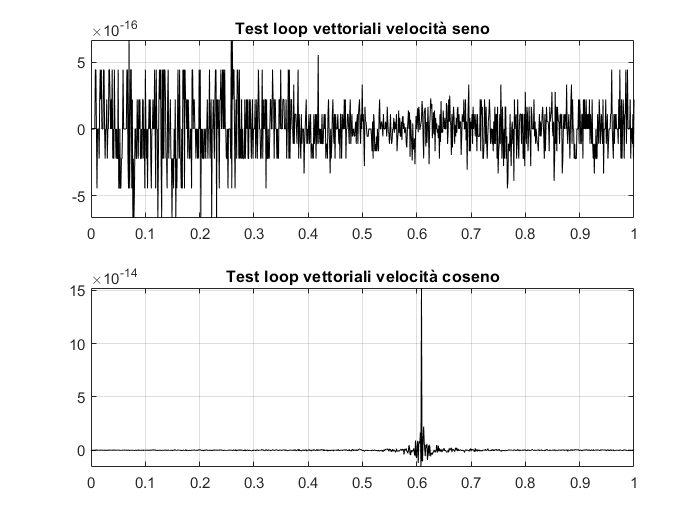

theta3_p =    -1.0719   -1.0612   -1.0507   -1.0402   -1.0298   -1.0195   -1.0092   -0.9990   -0.9889   -0.9789   -0.9689   -0.9591   -0.9492   -0.9395   -0.9298   -0.9202   -0.9107   -0.9012   -0.8918   -0.8825   -0.8732   -0.8640   -0.8549   -0.8458   -0.8368   -0.8279   -0.8190   -0.8102   -0.8015   -0.7928   -0.7841   -0.7756   -0.7670   -0.7586   -0.7502   -0.7418   -0.7336   -0.7253   -0.7172   -0.7090   -0.7010   -0.6930   -0.6850   -0.6771   -0.6693   -0.6615   -0.6537   -0.6460   -0.6384   -0.6308


theta4_p =     1.0719    1.0834    1.0948    1.1061    1.1173    1.1284    1.1394    1.1503    1.1611    1.1718    1.1824    1.1929    1.2033    1.2136    1.2238    1.2340    1.2440    1.2540    1.2638    1.2736    1.2833    1.2928    1.3023    1.3118    1.3211    1.3303    1.3395    1.3486    1.3576    1.3665    1.3753    1.3841    1.3928    1.4013    1.4099    1.4183    1.4267    1.4350    1.4432    1.4513    1.4594    1.4674    1.4753    1.4831    1.4909    1.4986    1.5063    1.5138    1.5213    1.5288


J34 =    -0.5359    0.5359   -0.5320    0.5348   -0.5281    0.5336   -0.5242    0.5325   -0.5204    0.5314   -0.5166    0.5304   -0.5129    0.5293   -0.5091    0.5283   -0.5054    0.5273   -0.5018    0.5263   -0.4981    0.5254   -0.4945    0.5244   -0.4909    0.5235   -0.4874    0.5226   -0.4839    0.5218   -0.4804    0.5209   -0.4770    0.5201   -0.4735    0.5192   -0.4701    0.5184   -0.4668    0.5177   -0.4634    0.5169   -0.4601    0.5162   -0.4568    0.5154   -0.4536    0.5147   -0.4504    0.5140
    0.6944   -0.6944    0.6979   -0.6943    0.7012   -0.6941    0.7045   -0.6939    0.7077   -0.6936    0.7108   -0.6933    0.7138   -0.6930    0.7167   -0.6927    0.7196   -0.6923    0.7224   -0.6918    0.7251   -0.6914    0.7277   -0.6909    0.7303   -0.6904    0.7328   -0.6899    0.7352   -0.6893    0.7375   -0.6887    0.7398   -0.6881    0.7420   -0.6874    0.7441   -0.6867    0.7462   -0.6860    0.7482   -0.6853    0.7502   -0.6845    0.7521   -0.6837    0.7539   -0.6829    0.7556   

[theta3_p,theta4_p,J34] = Theta34p(theta1ldm,theta2ldm,theta3,theta4,theta1ldm_p,theta2ldm_p)

**Analisi di accelerazione**

theta1ldm_pp = theta1_p + Ldm_theta1.moto.data{3,1}.v;
theta2ldm_pp = theta2_p + Ldm_theta2.moto.data{3,1}.v;
thetavldm_pp = thetaV_p + Ldm_thetav.moto.data{3,1}.v;

% % Test
% figure
% plot(time, theta1ldm_pp,'color','r')
% hold on
% plot(time,sqrt(theta1ldm_p.^4 + theta1ldm_pp.^2),'color','b')
% [J_p] = CalcoloJacobiana(PKM, theta1ldm,theta2ldm, theta1ldm_p,theta2ldm_p,P_p,P)

Theta_pp = [theta1ldm_pp;theta2ldm_pp;thetavldm_pp]

Theta_pp =          0   -0.0030   -0.0060   -0.0090   -0.0120   -0.0150   -0.0180   -0.0210   -0.0240   -0.0270   -0.0300   -0.0330   -0.0360   -0.0390   -0.0420   -0.0450   -0.0480   -0.0510   -0.0541   -0.0571   -0.0601   -0.0631   -0.0661   -0.0691   -0.0721   -0.0751   -0.0781   -0.0811   -0.0841   -0.0871   -0.0901   -0.0931   -0.0961   -0.0991   -0.1021   -0.1051   -0.1081   -0.1111   -0.1141   -0.1171   -0.1201   -0.1231   -0.1261   -0.1291   -0.1321   -0.1351   -0.1381   -0.1411   -0.1441   -0.1471
         0   -0.0010   -0.0020   -0.0030   -0.0040   -0.0050   -0.0060   -0.0070   -0.0080   -0.0090   -0.0100   -0.0110   -0.0120   -0.0130   -0.0140   -0.0150   -0.0160   -0.0170   -0.0180   -0.0190   -0.0200   -0.0210   -0.0220   -0.0230   -0.0240   -0.0250   -0.0260   -0.0270   -0.0280   -0.0290   -0.0300   -0.0310   -0.0320   -0.0330   -0.0340   -0.0350   -0.0360   -0.0370   -0.0380   -0.0390   -0.0400   -0.0410   -0.0420   -0.0430   -0.0440   -0.0450   -0.0460   -0.0470   -0.04

[P_pp] = Cinematica_Diretta_Accelerazione2(PKM,Theta, Theta_p, Theta_pp, P, P_p)

P_pp =    -2.5915   -2.5628   -2.5343   -2.5060   -2.4779   -2.4500   -2.4224   -2.3949   -2.3677   -2.3406   -2.3138   -2.2872   -2.2607   -2.2345   -2.2084   -2.1826   -2.1569   -2.1315   -2.1062   -2.0811   -2.0562   -2.0315   -2.0070   -1.9826   -1.9584   -1.9344   -1.9106   -1.8870   -1.8635   -1.8402   -1.8171   -1.7941   -1.7713   -1.7487   -1.7262   -1.7039   -1.6818   -1.6598   -1.6379   -1.6163   -1.5947   -1.5734   -1.5522   -1.5311   -1.5102   -1.4894   -1.4688   -1.4483   -1.4280   -1.4078
   -1.5579   -1.5569   -1.5561   -1.5553   -1.5545   -1.5538   -1.5532   -1.5526   -1.5521   -1.5516   -1.5512   -1.5508   -1.5505   -1.5502   -1.5499   -1.5497   -1.5495   -1.5494   -1.5493   -1.5492   -1.5491   -1.5491   -1.5491   -1.5491   -1.5492   -1.5493   -1.5493   -1.5495   -1.5496   -1.5497   -1.5499   -1.5500   -1.5502   -1.5504   -1.5506   -1.5508   -1.5510   -1.5512   -1.5515   -1.5517   -1.5519   -1.5522   -1.5524   -1.5526   -1.5529   -1.5531   -1.5533   -1.5536   -1.5538  

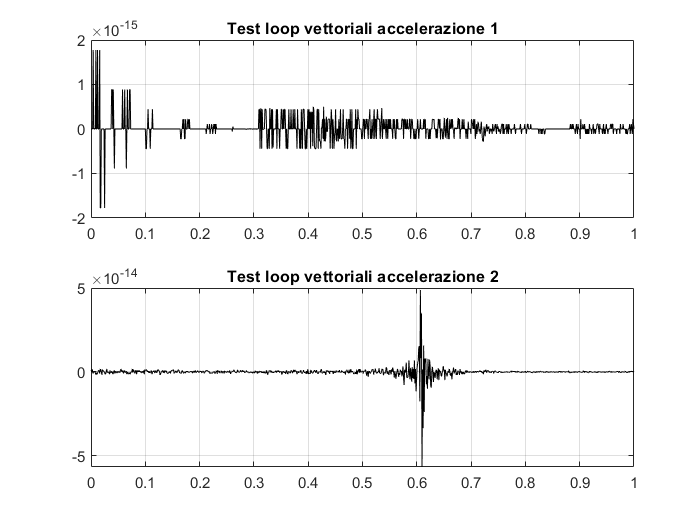

theta3_pp =    10.6678   10.5887   10.5104   10.4328   10.3559   10.2798   10.2044   10.1297   10.0557    9.9824    9.9098    9.8379    9.7667    9.6962    9.6263    9.5571    9.4885    9.4206    9.3534    9.2868    9.2208    9.1555    9.0908    9.0267    8.9632    8.9003    8.8380    8.7763    8.7152    8.6547    8.5948    8.5354    8.4766    8.4184    8.3607    8.3036    8.2470    8.1910    8.1355    8.0805    8.0260    7.9721    7.9187    7.8658    7.8134    7.7615    7.7101    7.6591    7.6087    7.5588


theta4_pp =    11.5544   11.4490   11.3446   11.2411   11.1386   11.0371   10.9365   10.8369   10.7382   10.6405   10.5436   10.4477   10.3526   10.2584   10.1652   10.0728    9.9812    9.8905    9.8007    9.7117    9.6235    9.5361    9.4496    9.3638    9.2789    9.1947    9.1113    9.0287    8.9469    8.8658    8.7854    8.7058    8.6270    8.5488    8.4714    8.3947    8.3187    8.2433    8.1687    8.0948    8.0215    7.9489    7.8769    7.8056    7.7350    7.6649    7.5956    7.5268    7.4587    7.3911


[theta3_pp,theta4_pp] = Theta34pp(theta1ldm,theta2ldm,theta3,theta4,theta1ldm_p,theta2ldm_p,...
    theta3_p,theta4_p,theta1ldm_pp, theta2ldm_pp)

## Cinematica Inversa

**Analisi di posizione**

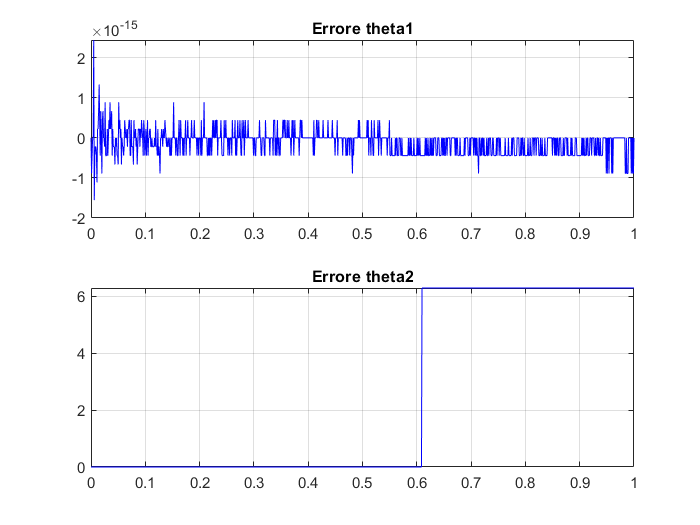

[theta1inv,theta2inv] = Cinematica_Inversa_Posizione(P, PKM, theta1ldm, theta2ldm);
Errore_theta1 = theta1ldm - theta1inv;
Errore_theta2 = theta2ldm - theta2inv;
time = linspace(0,1,length(Theta_p));

figure
subplot(2,1,1);
plot(time,Errore_theta1,'color','b')
title('Errore theta1')
grid on
subplot(2,1,2); 
plot(time,Errore_theta2,'color','b')
title('Errore theta2')
grid on

**Rappresentazione grafica**

%animation(PKM.link.d, PKM.link.l,theta1inv,theta2inv,theta3,theta4)

**Analisi di velocità**

Theta_p_inv = Cinematica_Inversa_Velocita(J,P_p);

**Analisi di accelerazione**

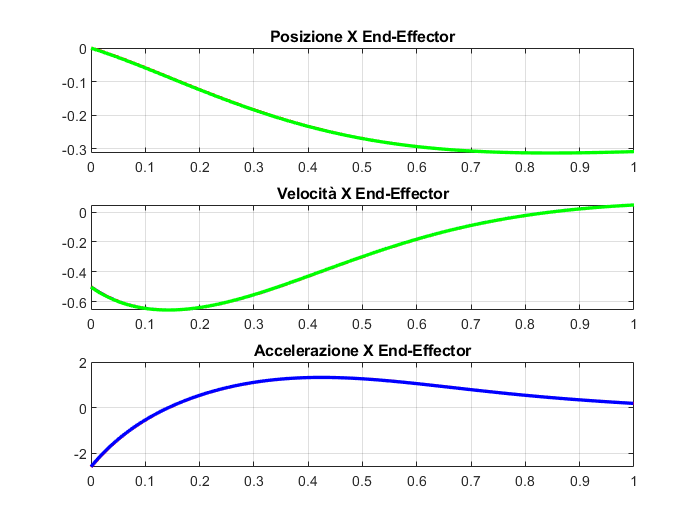

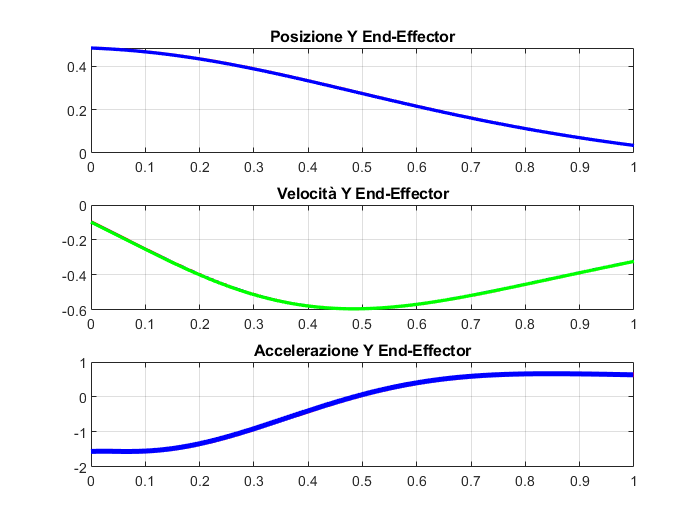

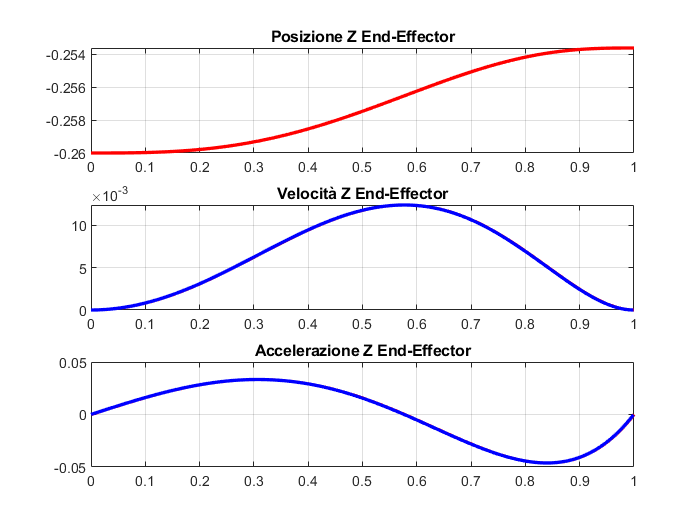

% Theta_pp_inv = Cinematica_Inversa_Accelerazione(J_p,J,Theta_p,P_pp);
load PKM_PosEF
load PKM_VelEF
Plot_EF(P, P_p, P_pp,PKM_PosEF,PKM_VelEF)

## Dinamica

#### 
$$\frac{d}{d\;t}\;\left(\frac{\partial \;T}{\partial \;\dot{q} }\right)-\;\frac{\partial \;T}{\partial \;q}\;+\;\frac{\partial \;U}{\partial \;q}\;=Q_q$$


#### 
$$T=\;\frac{1}{2}\;m\;{\left({\vartheta^˙ }_1 \;\frac{l}{2}\right)}^2 \;+\;\frac{1}{2}\;J{\;{\vartheta^˙ }_1 }^2 +\;\frac{1}{2}\;m\;{\left({\vartheta^˙ }_2 \;\frac{l}{2}\right)}^2 \;+\;\frac{1}{2}\;\mathrm{J}{\;{\vartheta^˙ }_2 }^2 +\;\frac{1}{2}\;m\;{v_{\textrm{c3}} }^2 \;+\;\frac{1}{2}\;J{\;{\vartheta^˙ }_3 }^2 +\;\frac{1}{2}\;m\;{v_{\textrm{c4}} }^2 \;+\;\frac{1}{2}\;J{\;{\vartheta^˙ }_4 }^2 +\;\frac{1}{2}\;m_e \;{v_e }^2 \;$$


#### 
$$U=m_e \;g\;\left(h+z\right)$$


Qtot = zeros(3,length(P));
for i=1:length(P)
[M, K, TN] = Matrici_Lagrange(PKM, theta1ldm(1,i), theta2ldm(1,i));
Q = M*Theta_pp(:,i) + K*(Theta_p(:,i).^2) + TN ;
Qtot(:,i) = Q;
end

[C1, C2] = Dinamica(PKM,theta1ldm,theta2ldm,theta3,theta4,theta1ldm_p,theta2ldm_p,theta3_p,theta4_p,...
    theta1ldm_pp,theta2ldm_pp,theta3_pp,theta4_pp,thetavldm_pp)

C1 =     1.3043    1.3032    1.3019    1.3004    1.2987    1.2968    1.2948    1.2926    1.2902    1.2877    1.2850    1.2822    1.2792    1.2761    1.2729    1.2695    1.2660    1.2624    1.2587    1.2548    1.2509    1.2468    1.2426    1.2384    1.2340    1.2296    1.2250    1.2204    1.2157    1.2109    1.2060    1.2011    1.1960    1.1910    1.1858    1.1806    1.1753    1.1700    1.1646    1.1591    1.1536    1.1481    1.1425    1.1368    1.1311    1.1254    1.1196    1.1138    1.1080    1.1021


C2 =     0.8078    0.7931    0.7786    0.7643    0.7502    0.7362    0.7225    0.7089    0.6955    0.6822    0.6692    0.6562    0.6435    0.6309    0.6184    0.6062    0.5940    0.5820    0.5702    0.5585    0.5469    0.5355    0.5242    0.5130    0.5019    0.4910    0.4802    0.4696    0.4590    0.4486    0.4383    0.4281    0.4180    0.4080    0.3982    0.3884    0.3787    0.3692    0.3597    0.3504    0.3411    0.3320    0.3229    0.3139    0.3050    0.2962    0.2875    0.2789    0.2704    0.2619



load PKM_Coppie
C1_adams = PKM_Coppie(:,1);
C2_adams = PKM_Coppie(:,2);
C1_adams = C1_adams';
C2_adams = C2_adams';

load PKM_Acc
[C1_PLV, C2_PLV] = Dinamica_PLV(PKM,theta1ldm,theta2ldm,theta3,theta4,theta1ldm_p,theta2ldm_p,theta3_p,theta4_p,...
    theta1ldm_pp,theta2ldm_pp,theta3_pp,theta4_pp,J34,PKM_Acc)

C1_PLV =     1.8569    1.8559    1.8547    1.8534    1.8520    1.8504    1.8488    1.8470    1.8451    1.8431    1.8410    1.8388    1.8365    1.8341    1.8316    1.8291    1.8265    1.8239    1.8211    1.8183    1.8155    1.8126    1.8097    1.8067    1.8037    1.8006    1.7975    1.7944    1.7912    1.7881    1.7849    1.7816    1.7784    1.7751    1.7719    1.7686    1.7653    1.7620    1.7587    1.7554    1.7521    1.7488    1.7455    1.7422    1.7389    1.7356    1.7323    1.7291    1.7258    1.7226


C2_PLV =     1.2115    1.2023    1.1934    1.1846    1.1761    1.1677    1.1595    1.1516    1.1437    1.1361    1.1286    1.1213    1.1142    1.1072    1.1004    1.0937    1.0872    1.0808    1.0746    1.0685    1.0626    1.0568    1.0511    1.0456    1.0402    1.0349    1.0297    1.0247    1.0198    1.0150    1.0103    1.0057    1.0013    0.9969    0.9927    0.9886    0.9845    0.9806    0.9768    0.9730    0.9694    0.9659    0.9624    0.9590    0.9558    0.9526    0.9495    0.9465    0.9436    0.9407


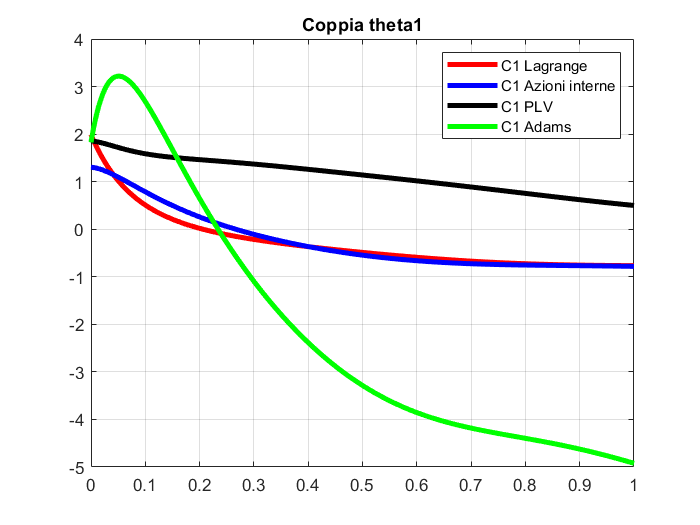


figure
plot(time,Qtot(1,:),'color','r','linewidth',3)
hold on
plot(time,C1(1,:),'color','b','linewidth',3)
hold on
plot(time,C1_PLV(1,:),'color','k','linewidth',3)
hold on
plot(time,C1_adams(1,:),'color','g','linewidth',3)
title('Coppia theta1')
legend('C1 Lagrange','C1 Azioni interne','C1 PLV','C1 Adams')
grid on

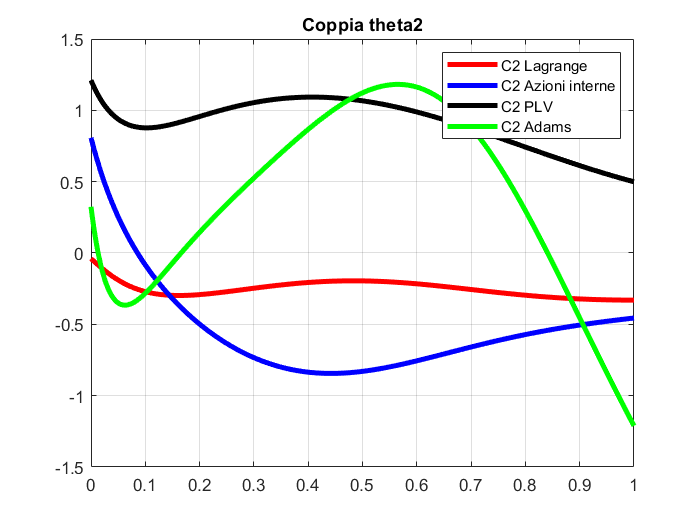


figure
plot(time,Qtot(2,:),'color','r','linewidth',3)
hold on
plot(time,C2(1,:),'color','b','linewidth',3)
hold on
plot(time,C2_PLV(1,:),'color','k','linewidth',3)
hold on
plot(time,C2_adams(1,:),'color','g','linewidth',3)
title('Coppia theta2')
legend('C2 Lagrange','C2 Azioni interne','C2 PLV','C2 Adams')
grid on

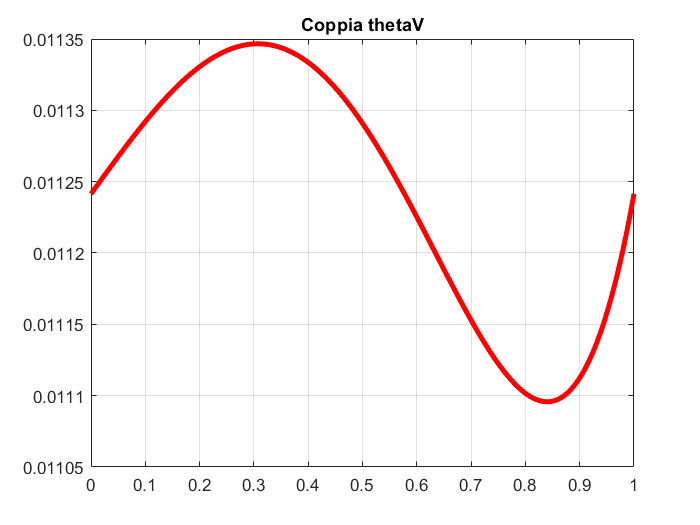


figure
plot(time,Qtot(3,:),'color','r','linewidth',3)
title('Coppia thetaV')
grid on


% figure
% plot(time,P(1,:)-x_ad,'color','r','linewidth',2)
% title('Posizione X End-Effector')
